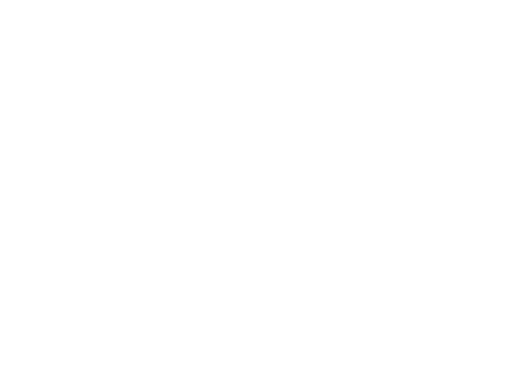

clear; close; clc;
%%% data aquizition
% state (X) should be columns of spatial variable and rows of snapshots.
% derivative (Xdot) should be the same shape as state.



%in this case we have state transposed so we must transpose it later

% assign state and derivative

% state = [1,2,3,4,5,6,7,8,9]
% derivative = [1,1,1,1,1,1,1,1,1]

% format them so each column is a spatial variable and each row a temporal
% snapshot.
% state = transpose(state)
% derivative = transpose(derivative)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%% simulate lorenze system %%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

mu = 1; % chaotic values
x0 = [0.1; 0.1]; % initial condition
dt = 0.001; % times step
timeSpan = dt:dt:50; % time span

% set otions to alow for more accurate simulation and control of error tolerances
% set relative tolerance to 10^-12 and absoute tolerence of each component
% to the 10^-12
options = odeset('RelTol',1e-12, 'AbsTol',1e-12*ones(1,2));

% output is time and the time history of state x
% wrap vdp function as function of x and t for ode45
% ode 45 wants time variable even though our DE is not time dependedent
[t,x] = ode45(@(t,x) vanderpol(t,x,mu), timeSpan, x0, options);
x = x * 1000;



figure;
plot(x(:,1), x(:,2), 'w', 'LineWidth', 1.5);
set(gca, 'color','k', 'xcolor','w', 'ycolor','w');
set(gcf, 'color','k');


%%% addnoise
%state = awgn(x,1e3);
state = x

state = 1.0e+03 *

    0.1000    0.1000
    0.1001    0.1000
    0.1002    0.1000
    0.1003    0.1000
    0.1004    0.1000
    0.1005    0.1000
    0.1006    0.1000
    0.1007    0.1000
    0.1008    0.1000
    0.1009    0.1000



figure;
plot(state(:,1), state(:,2), 'w', 'LineWidth', 1.5);
set(gca, 'color','k', 'xcolor','w', 'ycolor','w');
set(gcf, 'color','k');

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%% done with lorenze system %%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%% compute derivative %%%%%%%%%%

%%% if known
derivativeClean = zeros(size(state));
for i = 1:length(t)
    time = t(i);
    derivativeClean(i,:) = vanderpol(time,state(i,:),mu);
end

%%% from data
%derivative(:,1) = TVRegDiff(state(:,1),5,1e2,[],"large"); % these parameters do not work
%derivative(:,2) = TVRegDiff(state(:,2),5,1e2,[],"large"); % these parameters do not work
derivative(:,1) = TVRegDiff(state(:,1),10,.00002,[],"small",1e12,dt,0,1); %plot flag ste false to save time

pcg converged at iteration 46 to a solution with relative residual 9.3e-05.
iteration    1: relative change = 9.990e+02, gradient norm = 5.652e+05
pcg stopped at iteration 100 without converging to the desired tolerance 0.0001
because the maximum number of iterations was reached.
The iterate returned (number 87) has relative residual 0.024.
iteration    2: relative change = 5.185e-03, gradient norm = 5.279e+01
pcg stopped at iteration 100 without converging to the desired tolerance 0.0001
because the maximum number of iterations was reached.
The iterate returned (number 99) has relative residual 0.27.
iteration    3: relative change = 1.818e-03, gradient norm = 1.281e+00
pcg stopped at iteration 100 without converging to the desired tolerance 0.0001
because the maximum number of iterations was reached.
The iterate returned (number 98) has relative residual 0.71.
iteration    4: relative change = 7.809e-04, gradient norm = 3.503e-01
pcg stopped at iteration 100 without converging to the

derivative(:,2) = TVRegDiff(state(:,2),10,.00002,[],"small",1e12,dt,0,1);

pcg converged at iteration 62 to a solution with relative residual 8.3e-05.
iteration    1: relative change = 9.981e+02, gradient norm = 1.097e+06
pcg stopped at iteration 100 without converging to the desired tolerance 0.0001
because the maximum number of iterations was reached.
The iterate returned (number 97) has relative residual 0.11.
iteration    2: relative change = 2.512e-02, gradient norm = 9.149e+01
pcg stopped at iteration 100 without converging to the desired tolerance 0.0001
because the maximum number of iterations was reached.
The iterate returned (number 78) has relative residual 0.5.
iteration    3: relative change = 7.595e-03, gradient norm = 9.876e+00
pcg stopped at iteration 100 without converging to the desired tolerance 0.0001
because the maximum number of iterations was reached.
The iterate returned (number 70) has relative residual 0.44.
iteration    4: relative change = 2.512e-03, gradient norm = 4.978e+00
pcg stopped at iteration 100 without converging to the d

derivative = derivative(1:end-1,:); % may be needed if scale set to small?

%%%%%%%%% derivative found %%%%%%%%%%%%


%%%% check validity of derivative %%%%%
figure
plot(derivative);
hold on;
plot(derivativeClean);

%%% done validating of derivative %%%%%


%%% generate library of nonlinear candidate functions (Theta)
% dimentions are (snapshots x potential functions) i.e. (rows x columns)

% list of functions we would like
requestedFunctions = ["const","linear","poly2","poly3"]; % constant and linear terms

% declare library of candiate Functions
Theta = [];
numberOfSpatialVars = size(state,2)

numberOfSpatialVars = 2


% assemble library of candiate non-linear functions from columns
for candiateFunction = requestedFunctions()
switch(candiateFunction) % generate the columns associated with list of functions
    case "const"
        constFunc = ones(size(state,1),1)
        Theta = [Theta, constFunc];
    case "linear"
        linearFunc = state;
        Theta = [Theta, linearFunc];
    case "poly2"
        for i = 1:size(state,2)
            for j = i:size(state,2)
                Theta = [Theta, state(:,i).*state(:,j)];
            end
        end
    case "poly3"
        for i = 1:size(state,2)
            for j = i:size(state,2)
                for k = j:size(state,2)
                    Theta = [Theta, state(:,i).*state(:,j).*state(:,k)];
                end
            end
        end
    otherwise
        fprintf("%s not a recognized function \n",candiateFunction);
end
end

constFunc =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1







%%% generate the matrix of vecotrs of sparse coefficients (Xi)
% dimentions of Xi are (potential functions x spatial variables) i.e. (rows
% x columns) i.e. Xi = zeros(size(Theta,2),size(state,1)) 

%%% perform sparse regression to determine sparse coeffs of Xi
% we will be using sequatial threshold least squares algorithm which is a
% special case of SR3

% lambda is our threshold (sparsification knob) a value of 1 will be purely
% sparse (i.e. Xi will equal all 0s) and a value of 0 will be pure linear
% regresion (i.e. Xi = Theta \ Xdot)
lambda  = .5

lambda = 0.5000


Xi = Theta \ derivative;

for k = 1:10
    smallCoeffs = (abs(Xi)< lambda); % finds coefficients below the threshold
    Xi(smallCoeffs) = 0; % sets values smaller than threshold to 0
    for index = 1:size(state,2) % regress individually on the remaing coefficients
        bigIndecies = ~smallCoeffs(:,index); % find the terms affectign each variable that are still significant
        % regress dynamics onto remaining terms
        Xi(bigIndecies,index) = Theta(:,bigIndecies) \ derivative(:,index);
    end
end


Xi

Xi =          0         0
         0   -1.0213
    1.0000         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0



%%% SINDy algorithum is now complete


%%% plot the output in 2d
figure;
ROM = Theta*Xi

ROM = 1.0e+03 *

    0.1000   -0.1021
    0.1000   -0.1022
    0.1000   -0.1023
    0.1000   -0.1024
    0.1000   -0.1025
    0.1000   -0.1026
    0.1000   -0.1027
    0.1000   -0.1028
    0.1000   -0.1029
    0.1000   -0.1030


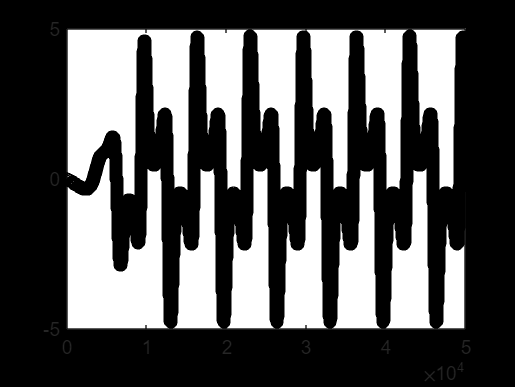

plot(t,ROM)

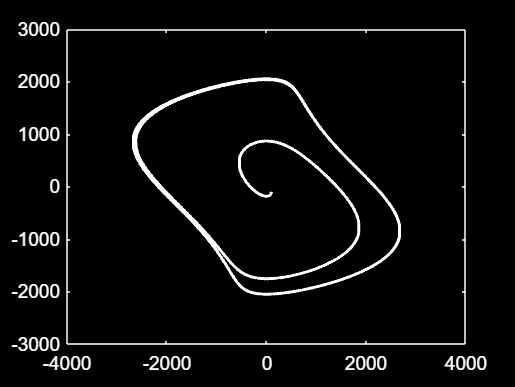


%%% plot the output in 3d
figure;
plot(ROM(:,1), ROM(:,2), 'w', 'LineWidth', 1.5);
set(gca, 'color','k', 'xcolor','w', 'ycolor','w');
set(gcf, 'color','k');

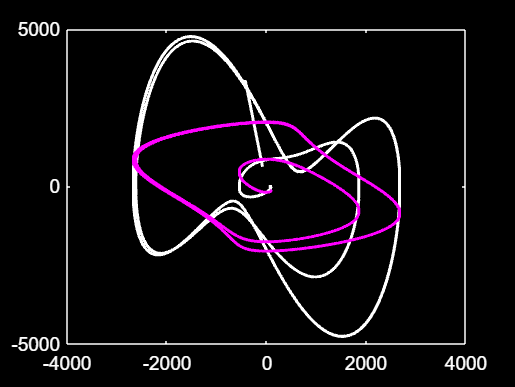


%%% plot original system and model together
figure;
plot(derivative(:,1), derivative(:,2), 'w', 'LineWidth', 1.5);
hold on;
plot(ROM(:,1), ROM(:,2), 'm', 'LineWidth', 1.5);
set(gca, 'color','k', 'xcolor','w', 'ycolor','w');
set(gcf, 'color','k');

function Xdot = diffeq(t,x)
    Xdot = [...
        atan(sin(x(1)) + 3),
        atan(x(1) * x(2) + 7),
        atan(x(3)^2 + x(1) - 2)
        ];
end

